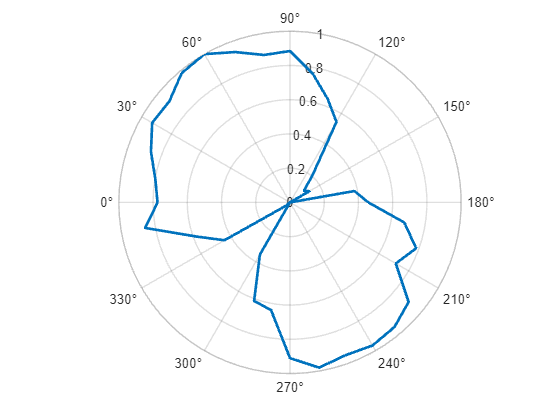

% Kąty w stopniach
angles_deg = 0:10:360;

% Przykładowe wartości dBFS
dbfs = [-8.0, -7.5, -6.2, -4.9, -5.1, -3.8, -3.5, -4.8, -6.0, -5.8, -8.2, -10.6, -12.6, -19.4, -21.3, -20.8, -23.4, -15.8, -14.3, -9.9, -7.8, -9.2, -5.4, -4.5, -4.2, -4.5, -3.9, -5.3, -10.7, -11.2, -16.4, -23.4, -22.8, -14.6, -11.8, -6.3, -8.0];

% Zamiana stopni na radiany
angles_rad = deg2rad(angles_deg);

% Normalizacja wartości
r = dbfs - min(dbfs);
r = r / (max(r) - min(r));

% Tworzenie wykresu biegunowego
ax = polaraxes;
polarplot(ax, angles_rad, r, 'LineWidth', 2);

% Ustawienie kątów osi
ax.ThetaZeroLocation = 'left'; % 0° po lewej
ax.ThetaDir = 'clockwise';     % kąty rosną zgodnie z ruchem wskazówek zegara